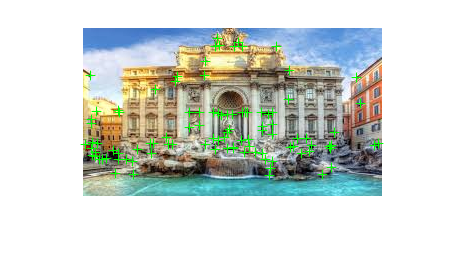

clear all
I1 = imread("FONT1.jpg");
I2 = imread("FONT2.jpg");
I3 = rgb2gray(I1); 
I4 = rgb2gray(I2);

corners =  detectHarrisFeatures(I3);
imshow(I1); hold on;
plot(corners.selectStrongest(100));
[features,puntos] = extractFeatures(I3,corners.selectStrongest(100));
hold off;

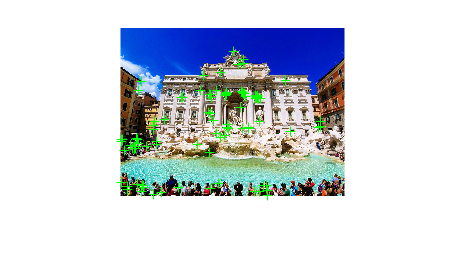


corners2 = detectHarrisFeatures(I4);
imshow(I2); hold on;
plot(corners2.selectStrongest(100));

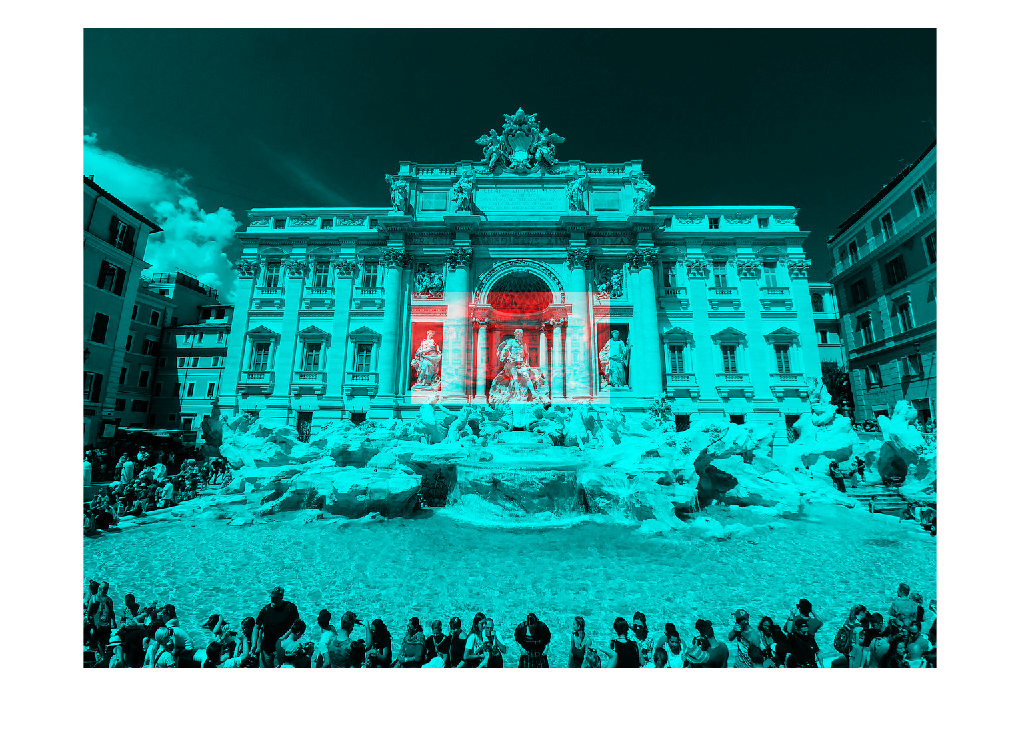

[features2,puntos2] = extractFeatures(I4,corners2.selectStrongest(100));

indexPairs = matchFeatures(features,features2,'Method','Threshold');
numMatchedPoints = int32(size(indexPairs,1));

matchedPA = puntos(indexPairs(:,1),:);
matchedPB = puntos2(indexPairs(:,2),:);
figure, showMatchedFeatures(I1,I2,matchedPA,matchedPB);

%points = detectSURFFeatures(I);
%imshow(I); hold on;
%plot(points.selectStrongest(1000));
